clear
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.




TF=71.52/(s^2+3.311*s+35.84)

TF =
 
          71.52
  ---------------------
  s^2 + 3.311 s + 35.84
 
Continuous-time transfer function.






C_c=pidtune(TF,"PID")

C_c =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 2.03, Ki = 5.38, Kd = 0.18
 
Continuous-time PID controller in parallel form.



C=C_c.Kp+C_c.Ki/s+C_c.Ki*s

C =
 
  5.378 s^2 + 2.032 s + 5.378
  ---------------------------
               s
 
Continuous-time transfer function.




c2d(C,2,"tustin")

ans =
 
  12.79 z^2 - 1.42e-15 z + 8.725
  ------------------------------
             z^2 - 1
 
Sample time: 2 seconds
Discrete-time transfer function.






num=[6.580782192615031 -18.891748968281533 18.051769213192244 -5.740768357921944]

num =     6.5808  -18.8917   18.0518   -5.7408



den=[1 2.751239739291020 -2.514650765653094 0.763411026362074]

den =     1.0000    2.7512   -2.5147    0.7634





C_d=tf(num,den,0.002)

C_d =
 
                                  
  6.581 z^3 - 18.89 z^2           
                                  
                 + 18.05 z - 5.741
                                  
  --------------------------------
                                  
  z^3 + 2.751 z^2 - 2.515 z       
                                  
                          + 0.7634
                                  
 
Sample time: 0.002 seconds
Discrete-time transfer function.



C_ic=d2c(C_d,"tustin")

C_ic =
 
                                  
  -9.796 s^3 - 668.1 s^2          
                                  
                   - 4202 s - 6776
                                  
  --------------------------------
                                  
  s^3 - 1005 s^2 - 1.188e06 s     
                                  
                        - 3.977e08
                                  
 
Continuous-time transfer function.




doc pidtune

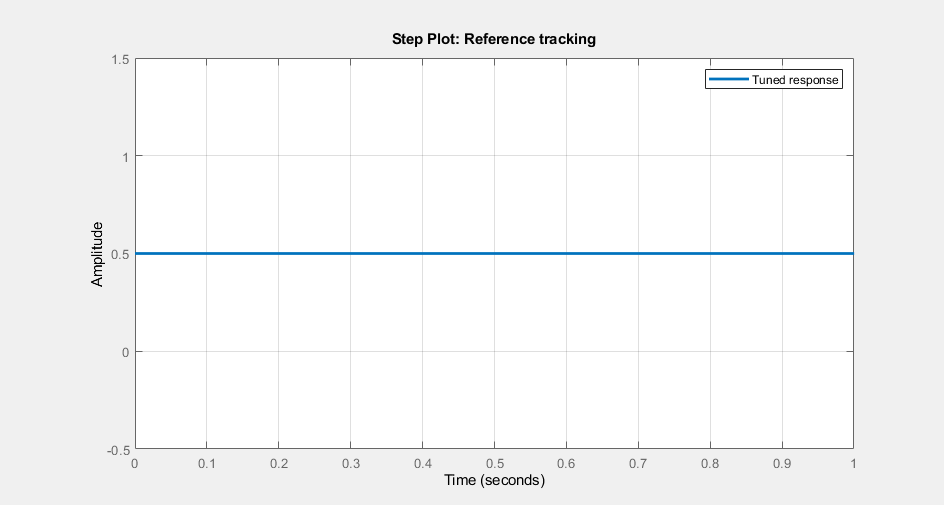

pidTuner